Function

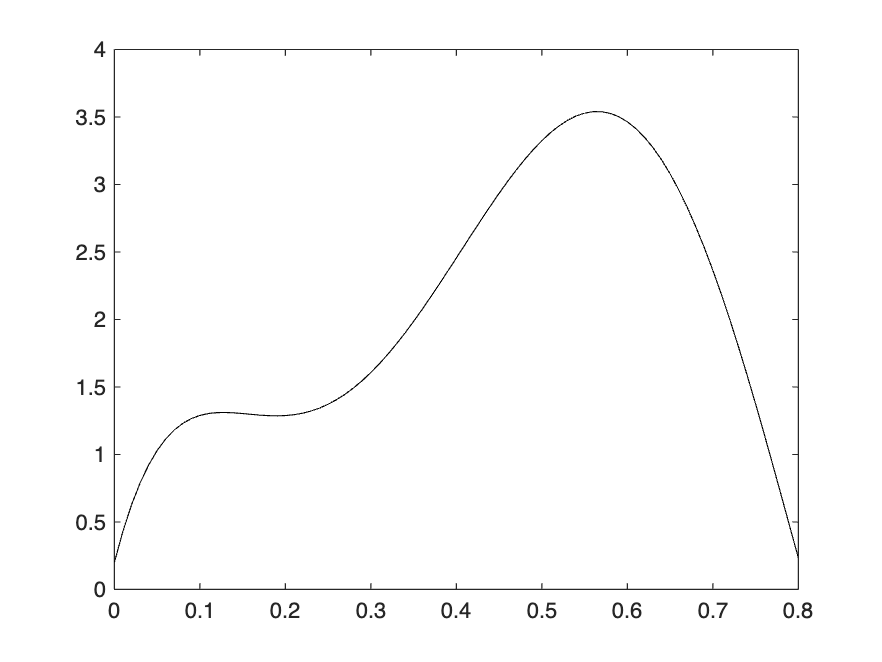

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0: 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, 'k-')

To integrate function from 0 to 0.8

format short

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000



q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1

ns = 1

ns = 1


x = linspace(0, 0.8, ns+1);
y = f(x)

y =     0.2000    0.2320


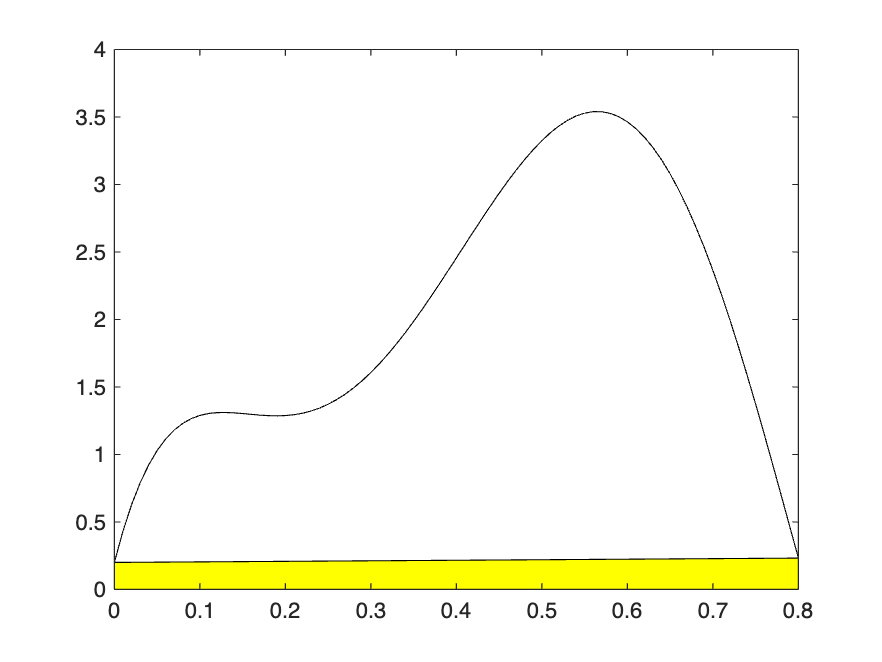


figure
area(x, y, 'FaceColor', 'y','EdgeColor','black', 'LineStyle','-')
hold on
plot(xx, yy, 'k-')

Plot original function along with trapezoidal rule ns = 2

ns = 2

ns = 2


x = linspace(0, 0.8, ns+1);
y = f(x)

y =     0.2000    2.4560    0.2320


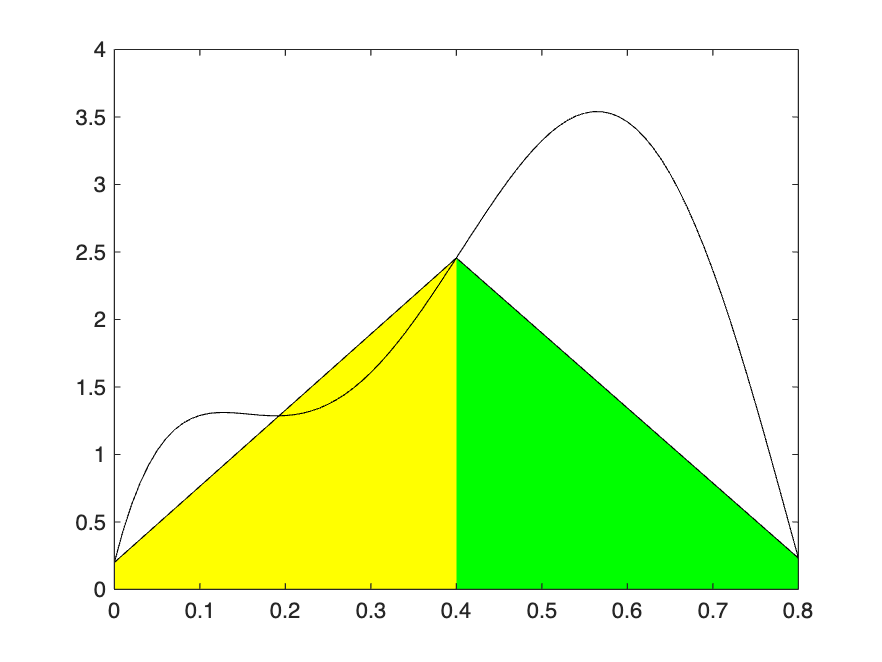


figure
color = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor', color(mod(i, 2)+1),'EdgeColor','black', 'LineStyle','-')
    hold on
end
plot(xx, yy, 'k-')

Plot original function along with trapezoidal rule ns = 3

ns = 3

ns = 3


x = linspace(0, 0.8, ns+1);
y = f(x)

y =     0.2000    1.4327    3.4872    0.2320


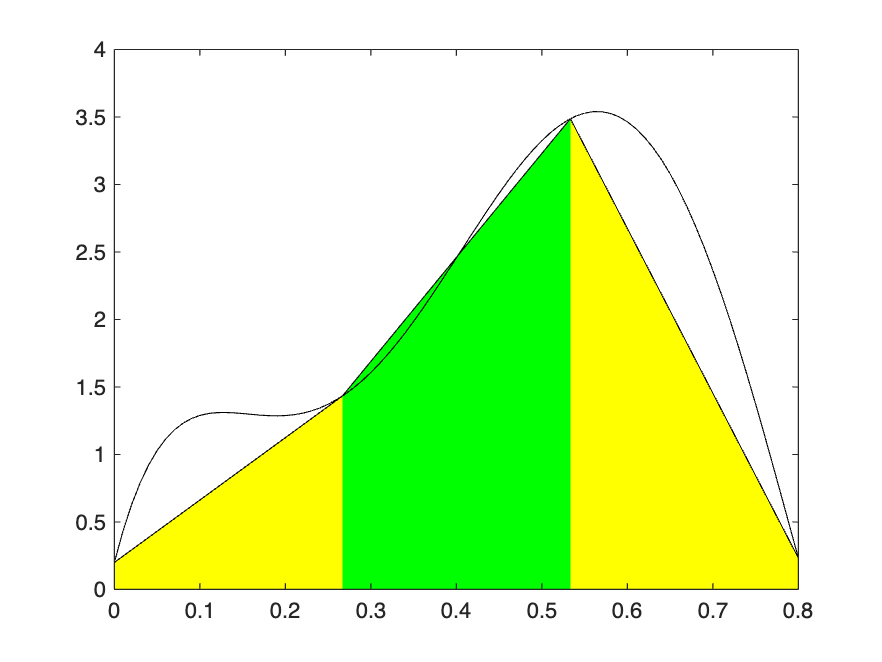


figure
color = ['g', 'y'];

for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor', color(mod(i, 2)+1),'EdgeColor','black', 'LineStyle','-')
    hold on
end
plot(xx, yy, 'k-')

Plot original function along with trapezoidal rule ns from 1 until 10

ns = 10

ns = 10

k = 1

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


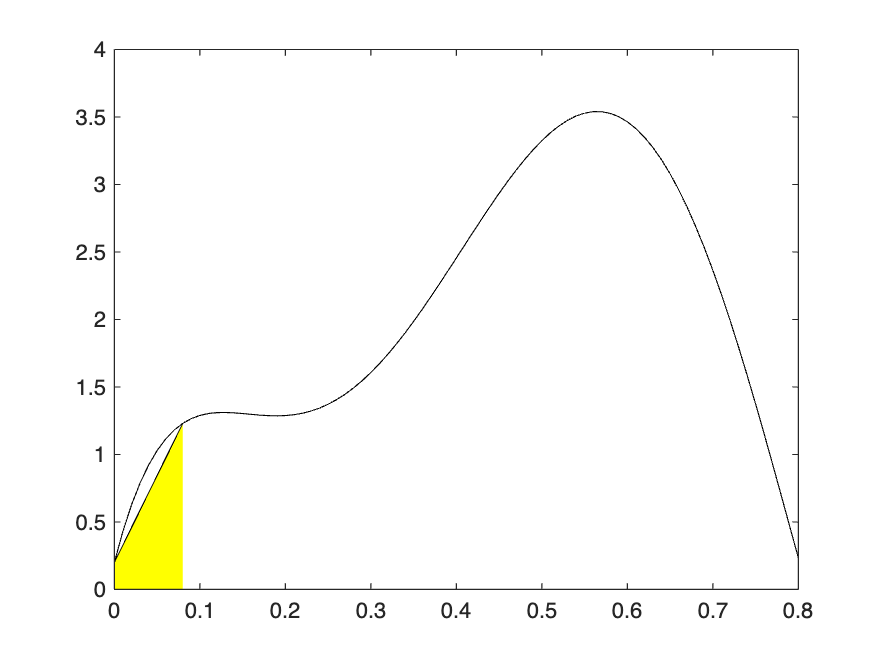

k = 2

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


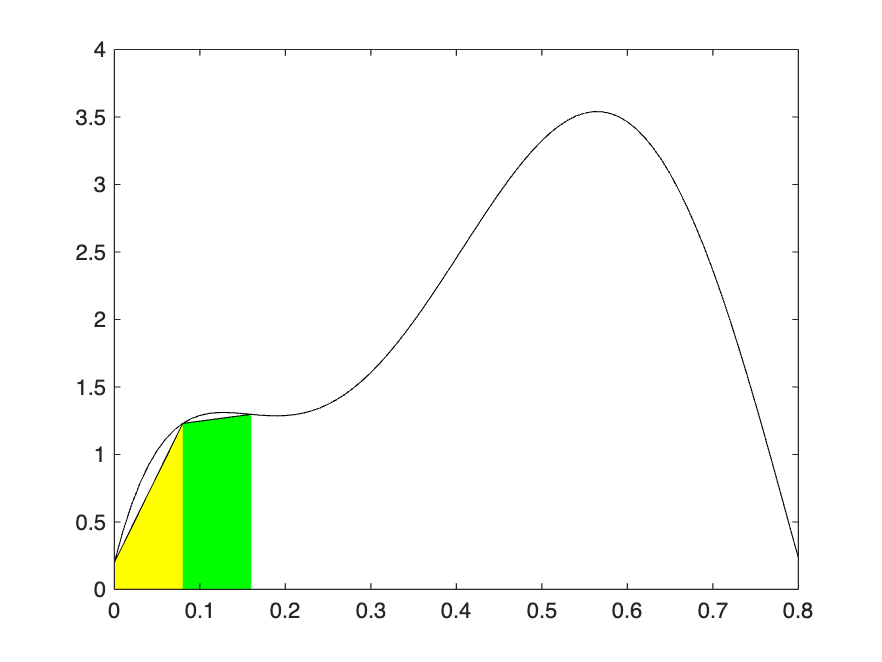

k = 3

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


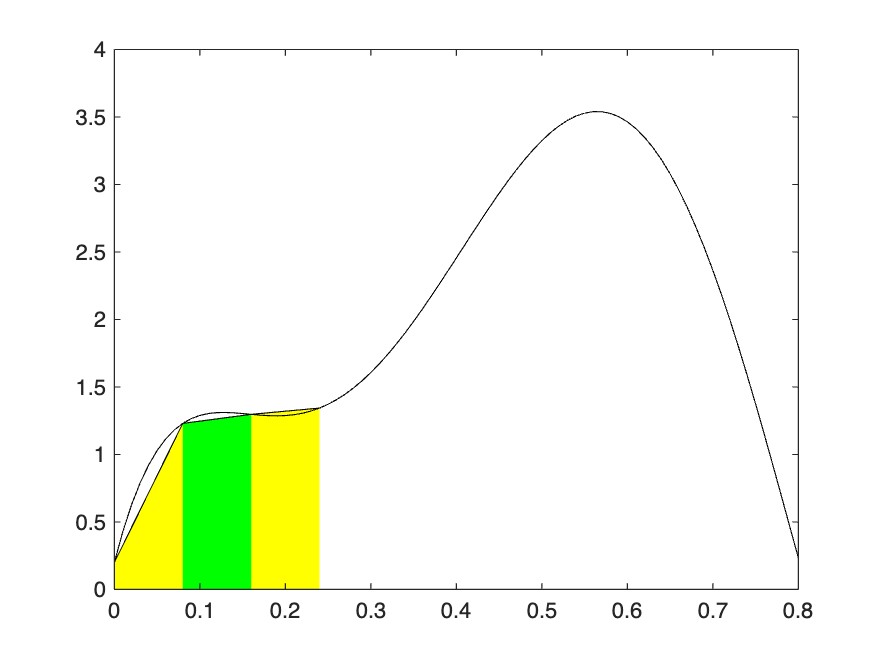

k = 4

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


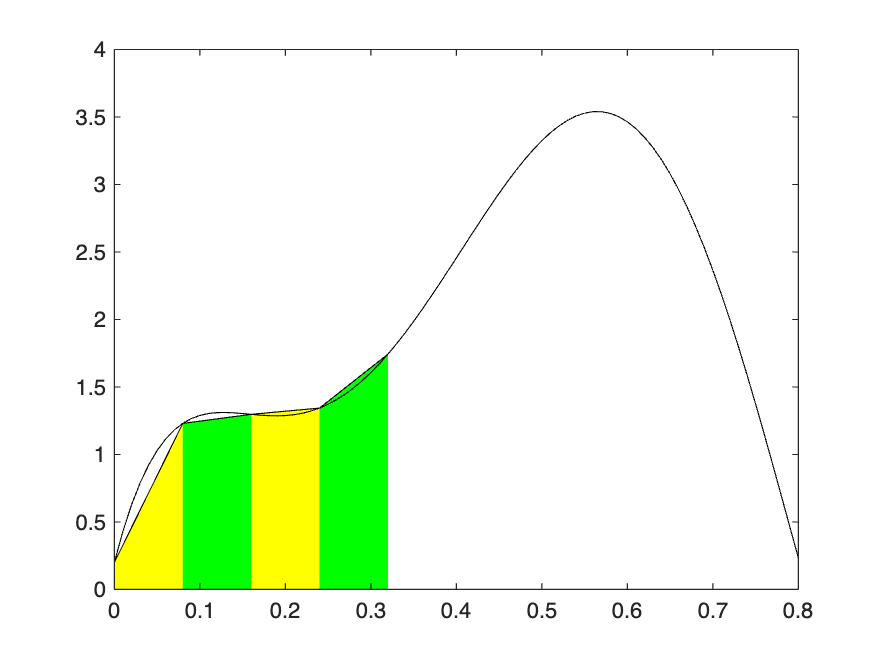

k = 5

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


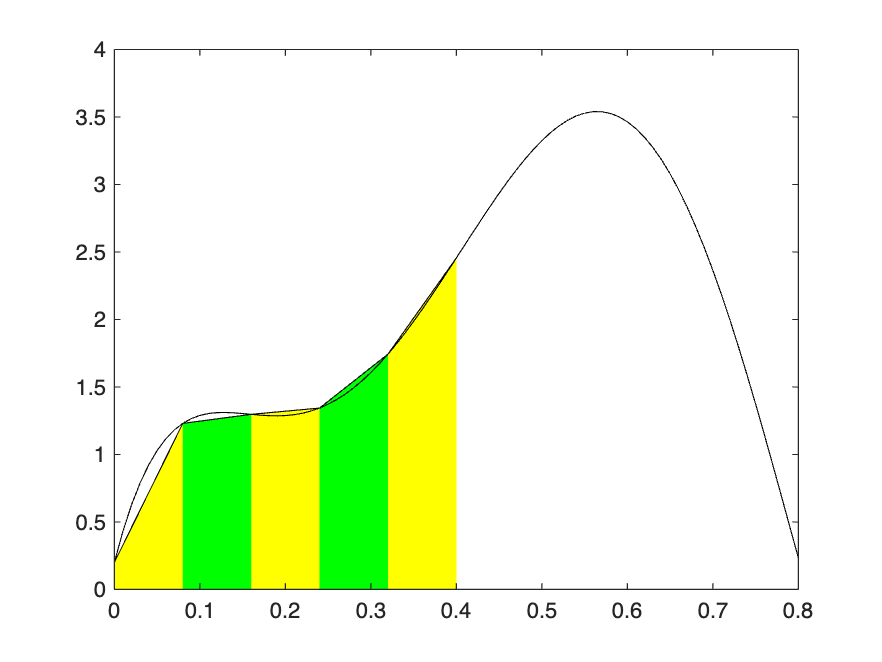

k = 6

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


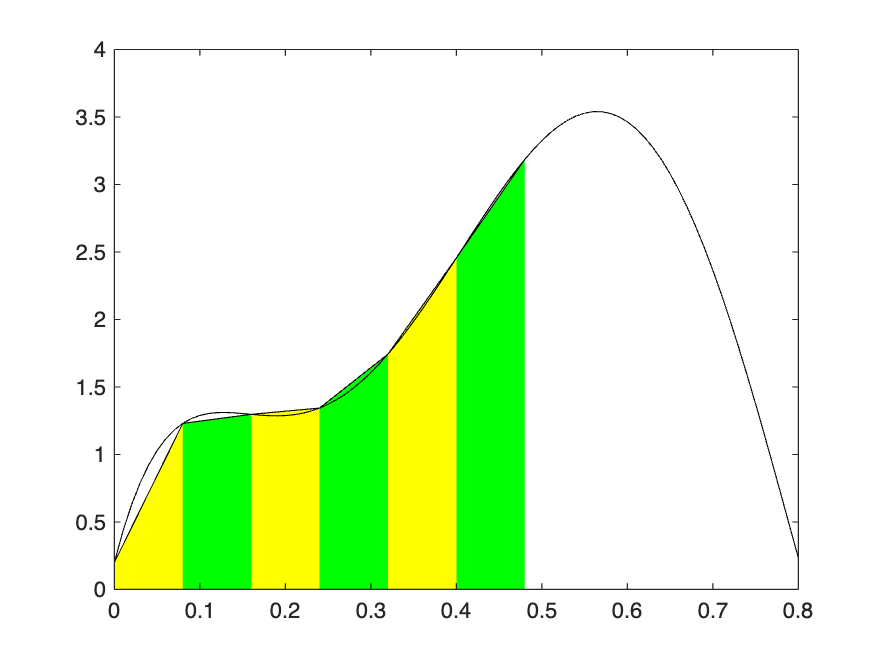

k = 7

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


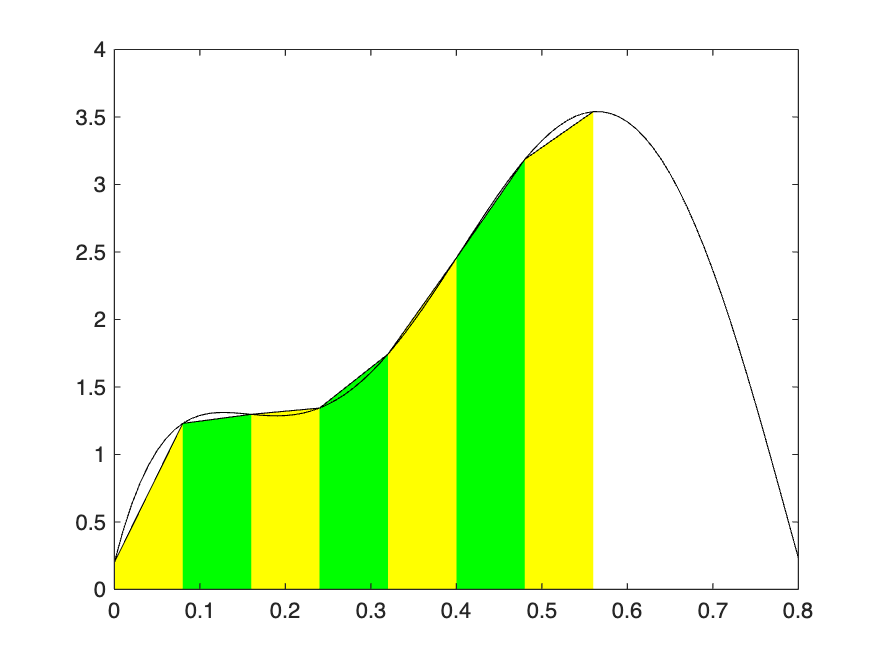

k = 8

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


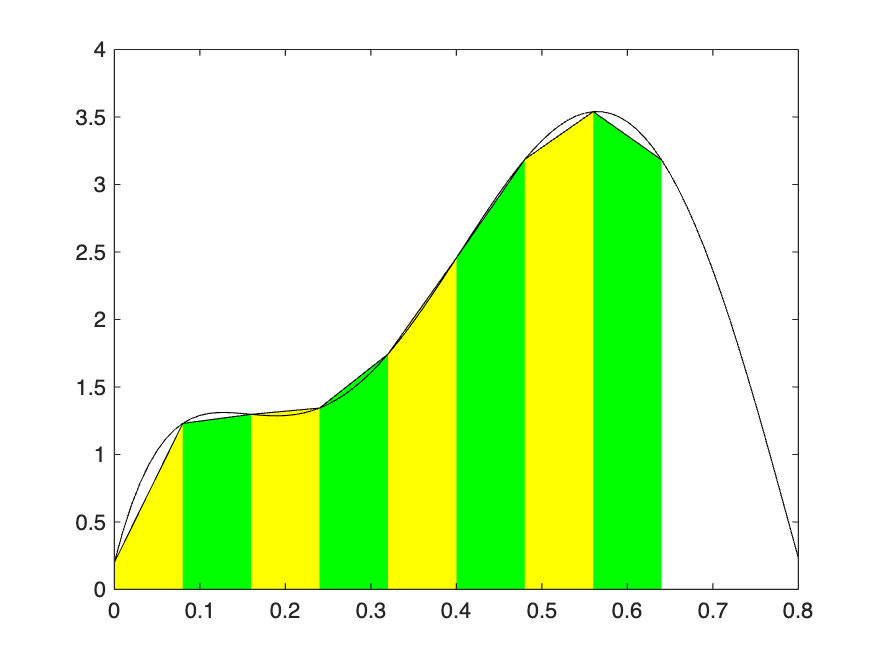

k = 9

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


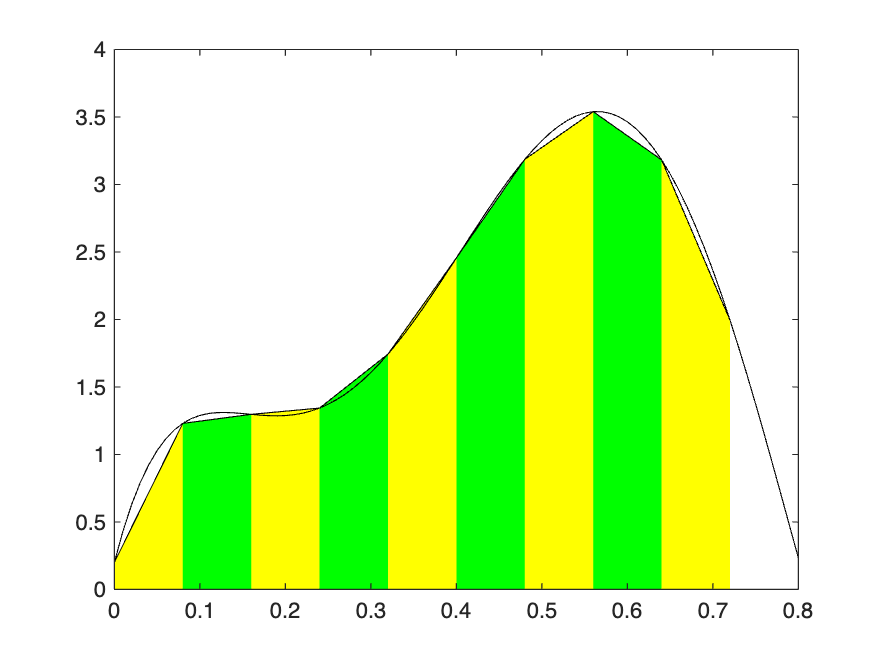

k = 10

y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


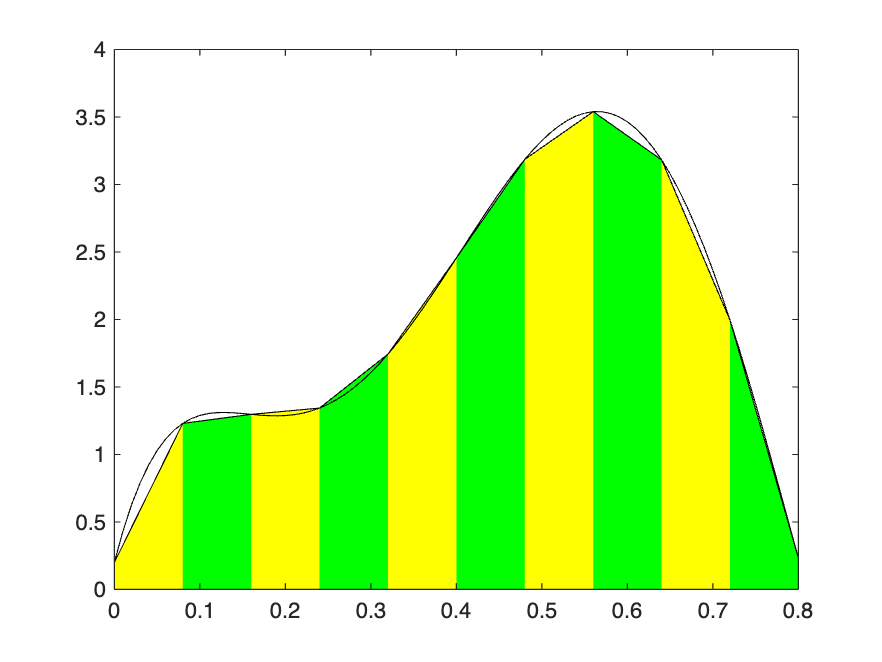


for k = 1:ns
    k

    x = linspace(0, 0.8, ns+1);
    y = f(x)

    figure
    color = ['g', 'y'];

    for i = 1:k
        area(x(i:i+1), y(i:i+1), 'FaceColor', color(mod(i, 2)+1),'EdgeColor','black', 'LineStyle','-')
        hold on
    end
    plot(xx, yy, 'k-')
end